clear;
noise_type_str = ["NO NOISE", "BIT FLIP", "DEPOLARIZING", "DEPHASING", "AMPLITUDE DAMPING"];


noise_p=0.001;
lambda=2;
offset=2;
dt=0.005;
nqubits=9;
init_cond=1;

## 提取$u_\mathrm{main}$

### 对每个 t, 拟合 u

对每个时刻t，拟合模型$u(x,t;D,E,F,G)=D\sin(E(x-Ft))+G$

modelEq = '$\ u(x,t;D,E,F,G)=D\sin(E(x-Ft))+G$';
function v = diffusion_model(p,x,t,lambda)
    D=p(1);
    E=p(2);
    F=p(3);
    G=p(4);
    v = D*sin(E*(x-F*t))+G ;
end

fig_fit = figure(Position=[0,0,1280,680]);
noise_types_list = [1,2,3,4];
for noise_type=noise_types_list
    name = strcat(noise_type_str(noise_type+1), num2str(noise_p),...
        '_lambda',num2str(lambda),...
        '_offset',num2str(offset),...
        '_dt', num2str(dt),...
        '_nqubits',num2str(nqubits),...
        '_initCond',num2str(init_cond));
    load(strcat('DATA/MAT_',name,'.mat'));
    
    % Fitting data to single wave modelEq
    D_opt = zeros(params.nsteps,1);
    E_opt = zeros(params.nsteps,1);
    F_opt = zeros(params.nsteps,1);
    G_opt = zeros(params.nsteps,1);
    resnorms = zeros(params.nsteps,1);% resnorm is the squared 2-norm of the residual(残差) at x: sum((fun(x,xdata)-ydata).^2).
    for i = 1:params.nsteps
        ui = u(i+1,:);
        % D E F G
        p_initial = [1.0, params.lambda, params.c,  params.offset];
        lb =        [0,   0,             0,         -Inf         ];
        ub =        [Inf, Inf,           2*pi,      Inf          ];
        options = optimoptions('lsqcurvefit', 'Display', 'iter', 'Algorithm','trust-region-reflective');
        [p_opt, resnorms(i)]=lsqcurvefit(@(p,x)diffusion_model(p,x,params.dt*(i),params.lambda), p_initial, x, ui, lb, ub, options);
        D_opt(i) = p_opt(1);
        E_opt(i) = p_opt(2);
        F_opt(i) = p_opt(3);
        G_opt(i) = p_opt(4);
    end
    save(strcat('DATA/SingleFit_',name,'.mat'),"D_opt","E_opt","F_opt","G_opt","resnorms","params","u");

    % Plot
    subplot(2,6,1:3);
    hold on;
    plot(t(2:end), D_opt, 'DisplayName',noise_type_str(noise_type+1),'LineWidth',1.0);
    hold off;
    
    subplot(2,6,7:8);
    hold on;
    plot(t(2:end),E_opt(1:end),LineWidth=1,DisplayName=noise_type_str(noise_type+1));
    hold off;
    
    subplot(2,6,9:10);
    hold on;
    plot(t(2:end),F_opt(1:end),LineWidth=1,DisplayName=noise_type_str(noise_type+1));
    hold off;
    
    subplot(2,6,4:6);
    hold on;
    plot(t(2:end),G_opt(1:end),LineWidth=1,DisplayName=noise_type_str(noise_type+1));
    hold off;
    
    subplot(2,6,11:12);
    hold on;
    plot(t(2:end),sqrt(resnorms(1:end)),LineWidth=1,DisplayName=noise_type_str(noise_type+1));
    hold off;
end


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          5         0.0089442                             1.37
     1         10       0.000725705       0.0181275          0.00721      
     2         15       0.000725493     0.000935382         1.53e-06      

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       op

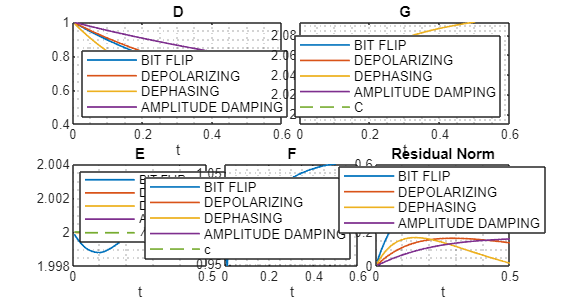


% Adjust format
subplot(2,6,1:3);
box on; grid minor;
legend(Location="southwest", FontSize=8);
xlabel('t');
title('D');

subplot(2,6,7:8);
hold on;
plot(t(2:end),ones(1,length(t)-1)*lambda, '--', DisplayName='\lambda',LineWidth=1);
hold off;
legend(Location="northwest",FontSize=7);
xlabel('t');
title('E')
box on; grid minor;

subplot(2,6,9:10);
hold on;
plot(t(2:end),ones(1,length(t)-1)*params.c, '--', DisplayName='c',LineWidth=1);
hold off;
legend(Location="southeast",FontSize=8);
xlabel('t');
title('F')
box on; grid minor;
    
subplot(2,6,4:6);
hold on;
plot(t(2:end),ones(1,length(t)-1)*offset, '--', DisplayName='C',LineWidth=1);
hold off;
ylim([offset-0.01, +Inf])
legend('location','southeast',FontSize=8)
xlabel('t');
title('G')
box on; grid minor;
    
subplot(2,6,11:12);
xlabel('t');
title('Residual Norm')
box on; grid minor;
legend(Location="best",FontSize=8);
% Save figure
figname=strcat('p', num2str(noise_p),...
    '_lambda',num2str(lambda),...
    '_offset',num2str(offset),...
    '_dt', num2str(dt),...
    '_nqubits',num2str(nqubits));
savefig(fig_fit, strcat('FIG/SingleFit_', figname,'.fig'))
exportgraphics(fig_fit, strcat('FIG/SingleFit_', figname,'.pdf'));

## 提取$u_\mathrm{main}$

### 对每个 t, 拟合 u

对每个时刻t，拟合模型$u(x,t;D,G)=D\sin(\lambda(x-ct))+G$

modelEq2 = '$\ u(x,t;D,G)=D\sin(\lambda(x-ct))+G$';
function v = u_model2(p,x,t)
    lambda = evalin("base", "lambda");
    c = evalin("base", "params.c");
    D=p(1);
    G=p(2);
    v = D*sin(lambda*(x-c*t))+G ;
end

### 以t为变量，拟合D,G


$$ D_\mathrm{main}(t;P,Q,R)=Pe^{Qt}+R, \\
        G_\mathrm{main}(t;X,Y,Z)=Xe^{Yt}+Z,$$


modelEq_D = '$\ D(t)=Pe^{Qt}+R$';
function v = D_model(p,t)
    P=p(1);
    Q=p(2);
    R=p(3);
    v = P*exp(Q*t)+R ;
end
modelEq_G = '$\ G(t)=Xe^{Yt}+Z$';
function v = G_model(p,t)
    P=p(1);
    Q=p(2);
    R=p(3);
    v = P*exp(Q*t)+R ;
end

noise_type = 1


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3         0.0108772                             1.51
     1          6       0.000826758      0.00605674          0.00884      
     2          9       0.000826449      3.4822e-05         3.08e-07      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           104.302                              102
     1          8           19.8947          3.4524               38      
     2         12           3.81862         5.10817             14.6      
     3         16          0.443564         1.95443             2.25      
     4         20          0.252024         7.49939              2.8      
     5         24         0.0473085        0.848346            0.181      
     6         28         0.0473085         1.21685            0.181      
     7         32         0.0300513        0.304213            0.113      
     8         36         0.0253853        0.608425            0.599      
     9         40        0.00639616       0.0867006           0.0272      
    10         44        0.00375312        0.152106           0.0539      
    11         48        0.00199938      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4            208.08                              144
     1          8         0.0174003         1.70956             1.01      
     2         12        0.00145122        0.115554           0.0259      
     3         16        0.00143087       0.0169646          0.00196      
     4         20        0.00143087        0.165324          0.00196      
     5         24        0.00141432        0.041331          0.00833      
     6         28        0.00139291       0.0497763           0.0131      
     7         32         0.0013741       0.0357756          0.00721      
     8         36        0.00134627       0.0667981           0.0247      
     9         40        0.00132476       0.0256147          0.00408      
    10         44        0.00129475        0.082662            0.039      
    11         48        0.00126069      

noise_type = 2


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3        0.00982952                             1.49
     1          6       6.57333e-05      0.00597014          0.00859      
     2          9       6.54421e-05     3.38283e-05         2.91e-07      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           99.9356                              100
     1          8           18.5906         3.31798             36.4      
     2         12           3.28659         4.53795             13.2      
     3         16          0.380088         1.81254             1.95      
     4         20          0.105725          6.1375             1.73      
     5         24         0.0234349        0.649474             0.29      
     6         28         0.0234349         1.39298             0.29      
     7         32         0.0153507        0.348246           0.0885      
     8         36        0.00803016        0.696491            0.228      
     9         40        0.00272777         0.25809           0.0836      
    10         44        0.00143372        0.325592            0.106      
    11         48       0.000489446      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           207.026                              144
     1          8          0.020068         1.72368              1.1      
     2         12        0.00114025        0.124765           0.0305      
     3         16        0.00111819        0.012237           0.0011      
     4         20        0.00111819        0.207049           0.0011      
     5         24        0.00110319       0.0517622           0.0124      
     6         28        0.00109203       0.0264328          0.00376      
     7         32        0.00107594       0.0835832           0.0353      
     8         36        0.00105426       0.0140618          0.00133      
     9         40        0.00104552       0.0208958          0.00227      
    10         44        0.00102831       0.0417916          0.00955      
    11         48        0.00100589      

noise_type = 3


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3         0.0388551                             2.97
     1          6       0.000255451       0.0118094           0.0336      
     2          9       0.000250943     0.000133451         4.51e-06      
     3         12       0.000250943      1.7916e-08         5.93e-11      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                              


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           126.398                              112
     1          8           27.0614         4.01098             45.1      
     2         12           7.30714          7.9279             21.4      
     3         16          0.930169         3.14006             3.99      
     4         20          0.372942              10             2.94      
     5         24         0.0599064        0.285967            0.339      
     6         28         0.0599064         2.27137            0.339      
     7         32         0.0351347        0.567842              0.2      
     8         36         0.0351347        0.735195              0.2      
     9         40         0.0179959        0.183799            0.179      
    10         44        0.00996817        0.367597           0.0449      
    11         48        0.00800504      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4            212.94                              146
     1          8         0.0156719         1.68985            0.846      
     2         12         0.0050564       0.0931686            0.017      
     3         16         0.0050008        0.055103           0.0175      
     4         20        0.00494156       0.0574305           0.0189      
     5         24        0.00487434       0.0604266           0.0216      
     6         28        0.00479926       0.0615724            0.023      
     7         32        0.00471198       0.0677608           0.0279      
     8         36        0.00461444       0.0682372           0.0279      
     9         40        0.00449733       0.0819492           0.0387      
    10         44        0.00436583       0.0791889           0.0334      
    11         48        0.00420591      

noise_type = 4


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3        0.00247283                            0.748
     1          6       1.67039e-05      0.00300222          0.00217      
     2          9       1.66854e-05     8.51901e-06         1.85e-08      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           82.8675                             90.9
     1          8           13.9878         2.76306             30.2      
     2         12           1.97563         2.38057              7.7      
     3         16          0.318508        0.355044            0.672      
     4         20         0.0181394         1.03005           0.0986      
     5         24        0.00474283        0.409982           0.0919      
     6         28        0.00474283        0.976944           0.0919      
     7         32        0.00350625        0.244236            0.049      
     8         36        0.00335871        0.488472            0.229      
     9         40        0.00140192       0.0291932          0.00559      
    10         44        0.00106715        0.122118           0.0112      
    11         48       0.000893356      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           202.046                              142
     1          8          0.256438         1.75237             4.95      
     2         12       0.000194698        0.152516           0.0454      
     3         16       0.000156929      0.00665588         0.000169      
     4         20       0.000156929         0.20829         0.000169      
     5         24       0.000154983       0.0520725          0.00899      
     6         28       0.000153536      0.00595618         0.000184      
     7         32       0.000151438       0.0520725          0.00971      
     8         36       0.000149768      0.00618763          0.00021      
     9         40       0.000147515       0.0520725           0.0105      
    10         44       0.000145577      0.00650787         0.000244      
    11         48       0.000143153      

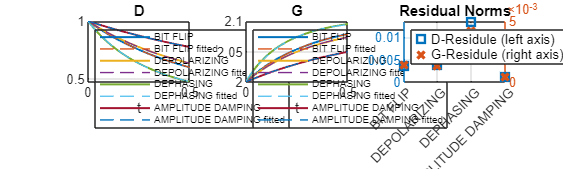

noise_type = 1


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3         0.0089442                             1.37
     1          6       0.000740914      0.00547474          0.00722      
     2          9       0.000740708     2.84279e-05         2.06e-07      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           100.305                              100
     1          8            18.693         3.32498             36.5      
     2         12           3.32059         4.58634             13.3      
     3         16          0.377501         1.94103             2.02      
     4         20         0.0939701         6.11114             1.62      
     5         24         0.0212852         0.89952            0.385      
     6         28         0.0150576        0.971133             0.53      
     7         32        0.00292583         0.06864           0.0182      
     8         36        0.00154293        0.242783            0.128      
     9         40        0.00043242        0.108929           0.0171      
    10         44       0.000228063        0.235271           0.0562      
    11         48       2.19477e-05      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           207.096                              144
     1          8         0.0204503         1.72523             1.11      
     2         12        0.00134259        0.124856           0.0305      
     3         16        0.00131968       0.0128789          0.00121      
     4         20        0.00131968        0.203501          0.00121      
     5         24        0.00130355       0.0508752           0.0119      
     6         28        0.00129082       0.0293114          0.00456      
     7         32        0.00127016       0.0753424           0.0287      
     8         36        0.00125227       0.0169109          0.00185      
     9         40        0.00124331         0.10175           0.0556      
    10         44        0.00119545       0.0162805          0.00157      
    11         48        0.00118199      

noise_type = 2


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3        0.00800458                             1.34
     1          6       6.05966e-05      0.00538786          0.00699      
     2          9       6.04036e-05     2.75287e-05         1.93e-07      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           96.9639                             98.5
     1          8           17.7326         3.22994             35.4      
     2         12           2.97584         4.16177             12.2      
     3         16          0.351857         1.55025              1.7      
     4         20         0.0720478           5.416             1.35      
     5         24         0.0247567          1.1566            0.538      
     6         28        0.00827007        0.429286            0.186      
     7         32        0.00543755         0.54809            0.256      
     8         36        0.00182702       0.0507027           0.0123      
     9         40        0.00122213        0.137023           0.0191      
    10         44       0.000845476        0.274045           0.0871      
    11         48       0.000265042      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           206.236                              144
     1          8         0.0217898         1.73175             1.15      
     2         12       0.000869893        0.130661           0.0336      
     3         16       0.000845687       0.0100331         0.000751      
     4         20       0.000845687        0.229423         0.000751      
     5         24       0.000833327       0.0573557           0.0147      
     6         28       0.000825364       0.0181412          0.00183      
     7         32       0.000825364        0.125833          0.00183      
     8         36        0.00081717       0.0286779          0.00396      
     9         40       0.000802462       0.0680965           0.0235      
    10         44       0.000790279       0.0154649          0.00151      
    11         48        0.00077384      

noise_type = 3


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3         0.0316878                             2.68
     1          6       0.000236015       0.0106706           0.0274      
     2          9       0.000233017      0.00010878            3e-06      
     3         12       0.000233017     1.18978e-08         2.32e-10      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                              


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           122.445                              111
     1          8           25.7223         3.92255             43.9      
     2         12           6.60274         7.42425             20.2      
     3         16          0.826631         2.83222             3.66      
     4         20          0.452651              10             3.43      
     5         24         0.0794029        0.918472            0.285      
     6         28         0.0794029         1.12871            0.285      
     7         32         0.0486526        0.282176            0.218      
     8         36         0.0258204        0.564353            0.538      
     9         40         0.0056857        0.316426           0.0839      
    10         44        0.00279027         0.58829             0.16      
    11         48        0.00037691      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           212.147                              146
     1          8         0.0150407         1.68882            0.853      
     2         12        0.00417063         0.09493           0.0176      
     3         16        0.00412391       0.0487466           0.0139      
     4         20        0.00406785       0.0640953           0.0231      
     5         24        0.00401645       0.0460151           0.0128      
     6         28        0.00394202       0.0866945           0.0443      
     7         32         0.0038754        0.036901          0.00856      
     8         36         0.0038754        0.161153          0.00856      
     9         40        0.00382536       0.0402882          0.00945      
    10         44        0.00373579       0.0805764            0.038      
    11         48        0.00363222      

noise_type = 4


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3        0.00201229                            0.674
     1          6       1.54021e-05      0.00270772          0.00177      
     2          9       1.53899e-05     6.92676e-06         1.23e-08      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           81.0707                             89.9
     1          8           13.5536         2.69848             29.5      
     2         12           1.90665         2.15762             7.15      
     3         16          0.321924        0.649943            0.638      
     4         20         0.0271459        0.812181            0.454      
     5         24        0.00599751        0.264057           0.0844      
     6         28        0.00599751        0.527228           0.0844      
     7         32        0.00473855        0.131807           0.0288      
     8         36         0.0032599        0.263614            0.128      
     9         40        0.00219837        0.263614           0.0734      
    10         44        0.00219837        0.401618           0.0734      
    11         48        0.00174953      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           201.446                              142
     1          8          0.625482         1.72631             7.85      
     2         12       0.000138158        0.149982           0.0382      
     3         16       0.000111609      0.00553655         0.000121      
     4         20       0.000111609         0.21097         0.000121      
     5         24       0.000110345       0.0527426          0.00867      
     6         28       0.000109134      0.00456454         0.000112      
     7         32       0.000107793       0.0527426          0.00938      
     8         36       0.000106391      0.00473805         0.000128      
     9         40       0.000104977       0.0527426           0.0101      
    10         44       0.000103344      0.00497748         0.000147      
    11         48       0.000101853      

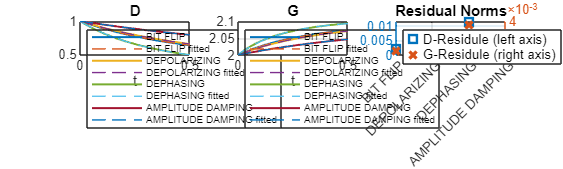

noise_type = 1


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3        0.00859376                             1.35
     1          6       0.000638433      0.00539177            0.007      
     2          9        0.00063824     2.75697e-05         1.93e-07      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           101.323                              101
     1          8           19.0043         3.37047               37      
     2         12           3.46246         4.73372             13.7      
     3         16          0.406613         1.69823                2      
     4         20          0.191654         6.80722             2.43      
     5         24         0.0395536        0.484161            0.113      
     6         28         0.0395536         1.15178            0.113      
     7         32         0.0252069        0.287944           0.0977      
     8         36         0.0228532        0.575888            0.599      
     9         40         0.0063656       0.0731083           0.0222      
    10         44         0.0039964        0.143972           0.0322      
    11         48        0.00238357      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           207.315                              144
     1          8           0.01844         1.71519             1.05      
     2         12        0.00111164        0.120296           0.0282      
     3         16        0.00109151       0.0135777          0.00132      
     4         20        0.00109151        0.191375          0.00132      
     5         24        0.00107634       0.0478438           0.0109      
     6         28        0.00106319       0.0319996           0.0055      
     7         32        0.00104299       0.0640116           0.0214      
     8         36        0.00102831       0.0210797          0.00273      
     9         40        0.00101646       0.0956876           0.0502      
    10         44       0.000976357        0.016332          0.00163      
    11         48       0.000964291      

noise_type = 2


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3        0.00984254                             1.49
     1          6       6.60148e-05      0.00597399           0.0086      
     2          9       6.57227e-05     3.38718e-05         2.92e-07      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           101.687                              101
     1          8           19.1155         3.38344             37.1      
     2         12           3.51008         4.78104             13.8      
     3         16          0.415064         1.66541             2.01      
     4         20          0.222114         6.96947             2.62      
     5         24         0.0456722        0.717888            0.146      
     6         28         0.0456722         1.23181            0.146      
     7         32         0.0295942        0.307953           0.0953      
     8         36         0.0172365        0.615907            0.102      
     9         40         0.0172365         1.30288            0.102      
    10         44         0.0118522        0.307953           0.0679      
    11         48        0.00805344      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           207.445                              144
     1          8         0.0177909         1.71189             1.04      
     2         12        0.00105694        0.118662           0.0274      
     3         16        0.00103763       0.0139299          0.00137      
     4         20        0.00103763        0.186326          0.00137      
     5         24        0.00102275       0.0465815           0.0105      
     6         28        0.00100922       0.0335308          0.00606      
     7         32       0.000989447       0.0591432           0.0185      
     8         36       0.000975162       0.0238987          0.00344      
     9         40       0.000961766       0.0931631            0.048      
    10         44       0.000924537       0.0165058          0.00168      
    11         48       0.000912895      

noise_type = 3


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3         0.0389713                             2.97
     1          6       0.000257439       0.0118266           0.0337      
     2          9       0.000252905     0.000133843         4.53e-06      
     3         12       0.000252905     1.80232e-08         6.33e-10      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                              


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4               132                              115
     1          8           29.1202         4.18222             47.1      
     2         12           8.53424          8.6825               23      
     3         16           1.21392         2.04396             4.29      
     4         20          0.547866              10             3.23      
     5         24          0.115236        0.153354            0.362      
     6         28          0.115236         1.18744            0.362      
     7         32         0.0702622         0.29686            0.265      
     8         36         0.0401432        0.593721            0.572      
     9         40         0.0106261         0.11673            0.049      
    10         44        0.00501011        0.593721            0.136      
    11         48        0.00134005      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           213.844                              146
     1          8         0.0132791         1.67114            0.745      
     2         12        0.00511135       0.0829359           0.0137      
     3         16        0.00503275       0.0814598           0.0384      
     4         20        0.00496981       0.0368649          0.00877      
     5         24        0.00496362        0.145238            0.125      
     6         28        0.00472394       0.0317595          0.00507      
     7         32        0.00466679       0.0363094          0.00748      
     8         36        0.00455776       0.0726188           0.0306      
     9         40        0.00440417        0.103753           0.0592      
    10         44        0.00423107        0.080403           0.0307      
    11         48        0.00407375      

noise_type = 4


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3        0.00247505                            0.748
     1          6        1.6814e-05      0.00300349          0.00217      
     2          9       1.67955e-05     8.52617e-06         1.85e-08      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           83.3473                             91.2
     1          8           14.1021         2.78431             30.4      
     2         12           1.99388         2.44786             7.87      
     3         16          0.315303        0.317291            0.674      
     4         20         0.0157761         1.11323           0.0737      
     5         24        0.00772798        0.569435            0.361      
     6         28        0.00334562       0.0795713           0.0222      
     7         32        0.00334562         1.09236           0.0222      
     8         36        0.00248507        0.273091           0.0833      
     9         40        0.00171694        0.265435             0.11      
    10         44        0.00103285       0.0672177           0.0126      
    11         48        0.00103285      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           202.199                              142
     1          8          0.140352         1.76437             3.58      
     2         12       0.000181956         0.15629           0.0492      
     3         16       0.000137974      0.00712969         0.000181      
     4         20       0.000137974        0.197735         0.000181      
     5         24       0.000136047       0.0494337          0.00833      
     6         28       0.000134731      0.00636747         0.000206      
     7         32       0.000132657       0.0494337          0.00897      
     8         36       0.000131153      0.00659051         0.000232      
     9         40       0.000128928       0.0494337          0.00964      
    10         44       0.000127197      0.00689763         0.000267      
    11         48       0.000124808      

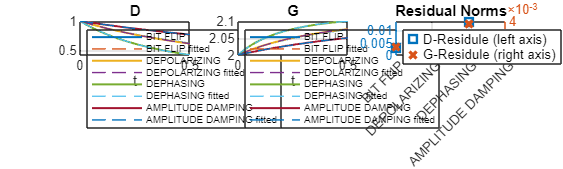

noise_type = 1


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3        0.00719378                             1.22
     1          6       0.000654377      0.00489064          0.00576      
     2          9       0.000654246     2.26674e-05         1.31e-07      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4            94.783                             97.3
     1          8           17.1175         3.13473             34.5      
     2         12            2.7471          3.8422             11.4      
     3         16          0.322504         1.80692              1.7      
     4         20         0.0335842         3.96868            0.368      
     5         24         0.0335842         3.06287            0.368      
     6         28         0.0180329        0.765716           0.0707      
     7         32         0.0180329        0.811429           0.0707      
     8         36         0.0121125        0.202857           0.0289      
     9         40        0.00538945        0.405715            0.195      
    10         44         0.0050396        0.874299            0.356      
    11         48       0.000536418      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           205.659                              143
     1          8         0.0269814         1.75473             1.28      
     2         12        0.00120962        0.141649             0.04      
     3         16        0.00117605      0.00937689         0.000633      
     4         20        0.00117605         0.24506         0.000633      
     5         24        0.00116375       0.0612651           0.0153      
     6         28        0.00115628       0.0160309          0.00139      
     7         32        0.00115628         0.12253          0.00139      
     8         36        0.00114793       0.0306326          0.00416      
     9         40         0.0011332       0.0598137           0.0169      
    10         44        0.00112366       0.0183022          0.00193      
    11         48        0.00110702      

noise_type = 2


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3        0.00636743                              1.2
     1          6       5.57808e-05      0.00480494          0.00556      
     2          9       5.56588e-05     2.18759e-05         1.22e-07      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           93.8453                             96.9
     1          8           16.8557         3.13418             34.3      
     2         12           2.68523         3.76745             11.2      
     3         16          0.329691         1.24185             1.42      
     4         20          0.048128         4.70606            0.989      
     5         24         0.0337397         1.55305            0.832      
     6         28        0.00856082         0.18898            0.045      
     7         32        0.00796487        0.388264            0.349      
     8         36        0.00269699       0.0353973           0.0113      
     9         40        0.00214894       0.0970659           0.0178      
    10         44        0.00148658        0.194132            0.101      
    11         48       0.000682059      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           205.375                              143
     1          8         0.0241363         1.74189             1.22      
     2         12       0.000638345         0.13768           0.0375      
     3         16        0.00061017      0.00850246         0.000514      
     4         20        0.00061017        0.245359         0.000514      
     5         24       0.000601056       0.0613398           0.0161      
     6         28       0.000594812        0.012861          0.00096      
     7         32       0.000584676       0.0613398           0.0175      
     8         36       0.000577239       0.0139439          0.00118      
     9         40        0.00056592       0.0613398           0.0188      
    10         44       0.000557067       0.0155238          0.00149      
    11         48       0.000544361      

noise_type = 3


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3         0.0252377                             2.39
     1          6       0.000217317        0.009527           0.0219      
     2          9       0.000215415      8.6574e-05          1.9e-06      
     3         12       0.000215415     7.52941e-09         4.27e-10      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                              


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           118.076                              109
     1          8           24.2687         3.81951             42.6      
     2         12           5.86047         6.86756             18.9      
     3         16          0.720104         2.55266              3.3      
     4         20          0.720104         11.2608              3.3      
     5         24          0.347482             2.5            0.339      
     6         28          0.183295         1.83417             1.76      
     7         32         0.0427881         1.02227            0.522      
     8         36          0.017123        0.924046            0.401      
     9         40        0.00412064        0.159609           0.0444      
    10         44        0.00323622        0.573537            0.178      
    11         48       0.000327763      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           211.238                              145
     1          8         0.0147161         1.68961             0.87      
     2         12        0.00330146       0.0978507           0.0186      
     3         16        0.00326447       0.0406842           0.0098      
     4         20        0.00321349       0.0760238           0.0317      
     5         24          0.003174       0.0309569          0.00607      
     6         28          0.003174        0.142159          0.00607      
     7         32        0.00314141       0.0355398          0.00717      
     8         36        0.00308176       0.0710796           0.0296      
     9         40        0.00302272       0.0466781           0.0135      
    10         44        0.00294849        0.101603            0.061      
    11         48        0.00285746      

noise_type = 4


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3         0.0015996                            0.601
     1          6        1.4228e-05      0.00241319           0.0014      
     2          9       1.42203e-05     5.49907e-06          7.8e-09      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           79.2342                             88.8
     1          8            13.121         2.63085             28.8      
     2         12           1.84899         1.93076              6.6      
     3         16          0.321254        0.994886            0.591      
     4         20         0.0323102        0.654468            0.614      
     5         24        0.00550409        0.201589            0.122      
     6         28        0.00523065        0.462582            0.355      
     7         32        0.00211759       0.0484068           0.0116      
     8         36        0.00177524        0.115645           0.0114      
     9         40        0.00137996        0.231291           0.0985      
    10         44       0.000887362        0.138497           0.0338      
    11         48       0.000840099      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           200.816                              142
     1          8           1.18795         1.69934             10.9      
     2         12       9.28778e-05         0.15446           0.0309      
     3         16       7.55126e-05      0.00444547         8.11e-05      
     4         20       7.55126e-05        0.215115         8.11e-05      
     5         24       7.48173e-05       0.0537788          0.00837      
     6         28       7.37758e-05      0.00335727         6.49e-05      
     7         32       7.30652e-05       0.0537788          0.00908      
     8         36       7.18515e-05      0.00349141         7.37e-05      
     9         40       7.11359e-05       0.0537788          0.00983      
    10         44       6.97153e-05      0.00367622         8.48e-05      
    11         48       6.90007e-05      

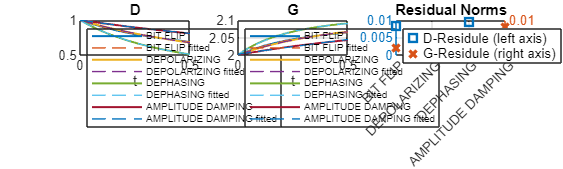

noise_type = 1


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3        0.00863104                             1.35
     1          6       0.000675227       0.0053919            0.007      
     2          9       0.000675033     2.75706e-05         1.94e-07      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           101.172                              101
     1          8           18.9591         3.36474             36.9      
     2         12           3.44268         4.71227             13.6      
     3         16          0.403578         1.71424                2      
     4         20           0.17888         6.73124             2.34      
     5         24         0.0371326        0.362481            0.106      
     6         28         0.0371326         1.13395            0.106      
     7         32         0.0235111        0.283488           0.0946      
     8         36         0.0218381        0.566976            0.595      
     9         40         0.0058999       0.0734125           0.0209      
    10         44        0.00369034        0.141744           0.0301      
    11         48        0.00218824      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           207.261                              144
     1          8         0.0187473         1.71684             1.06      
     2         12        0.00111578        0.121168           0.0286      
     3         16        0.00109534       0.0132749          0.00127      
     4         20        0.00109534        0.194688          0.00127      
     5         24         0.0010802       0.0486719           0.0112      
     6         28        0.00106754       0.0306746          0.00506      
     7         32        0.00104761       0.0679486            0.024      
     8         36        0.00103237       0.0190337          0.00227      
     9         40        0.00102228       0.0973438           0.0518      
    10         44       0.000980275       0.0161192          0.00157      
    11         48         0.0009681      

noise_type = 2


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3         0.0098433                             1.49
     1          6       6.59985e-05       0.0059742           0.0086      
     2          9       6.57065e-05      3.3874e-05         2.92e-07      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           101.687                              101
     1          8           19.1155         3.38344             37.1      
     2         12           3.51008         4.78104             13.8      
     3         16          0.415064         1.66541             2.01      
     4         20          0.222113         6.96947             2.62      
     5         24          0.045672        0.717883            0.146      
     6         28          0.045672         1.23181            0.146      
     7         32          0.029594        0.307953           0.0953      
     8         36         0.0172363        0.615905            0.102      
     9         40         0.0172363         1.30289            0.102      
    10         44         0.0118521        0.307953           0.0679      
    11         48        0.00805338      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           207.445                              144
     1          8         0.0177909         1.71189             1.04      
     2         12        0.00105695        0.118663           0.0274      
     3         16        0.00103764       0.0139299          0.00137      
     4         20        0.00103764        0.186327          0.00137      
     5         24        0.00102275       0.0465817           0.0105      
     6         28        0.00100922       0.0335307          0.00606      
     7         32       0.000989454       0.0591438           0.0185      
     8         36        0.00097517       0.0238983          0.00344      
     9         40       0.000961773       0.0931634            0.048      
    10         44       0.000924544       0.0165058          0.00168      
    11         48       0.000912902      

noise_type = 3


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3         0.0389731                             2.97
     1          6       0.000257628       0.0118268           0.0337      
     2          9       0.000253094     0.000133844         4.53e-06      
     3         12       0.000253094     1.80214e-08         7.87e-11      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                              


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4               132                              115
     1          8           29.1202         4.18222             47.1      
     2         12           8.53424          8.6825               23      
     3         16           1.21392         2.04396             4.29      
     4         20          0.547867              10             3.23      
     5         24          0.115236        0.153355            0.362      
     6         28          0.115236         1.18744            0.362      
     7         32         0.0702623         0.29686            0.265      
     8         36         0.0401433        0.593721            0.572      
     9         40         0.0106261        0.116729            0.049      
    10         44        0.00501013        0.593721            0.136      
    11         48        0.00134006      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           213.844                              146
     1          8         0.0132791         1.67114            0.745      
     2         12        0.00511134        0.082936           0.0137      
     3         16        0.00503274       0.0814599           0.0384      
     4         20         0.0049698       0.0368649          0.00877      
     5         24        0.00496361        0.145238            0.125      
     6         28        0.00472393       0.0317596          0.00507      
     7         32        0.00466678       0.0363095          0.00748      
     8         36        0.00455775        0.072619           0.0306      
     9         40        0.00440416        0.103753           0.0592      
    10         44        0.00423106       0.0804033           0.0307      
    11         48        0.00407374      

noise_type = 4


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3        0.00247525                            0.748
     1          6        1.6816e-05      0.00300363          0.00217      
     2          9       1.67974e-05     8.52706e-06         1.86e-08      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           83.3473                             91.2
     1          8           14.1021         2.78431             30.4      
     2         12           1.99388         2.44786             7.87      
     3         16          0.315303        0.317292            0.674      
     4         20         0.0157762         1.11323           0.0737      
     5         24        0.00772788        0.569432            0.361      
     6         28        0.00334563       0.0795811           0.0222      
     7         32        0.00334563         1.09234           0.0222      
     8         36        0.00248509        0.273084           0.0833      
     9         40        0.00171701        0.265446             0.11      
    10         44        0.00103287       0.0672062           0.0126      
    11         48        0.00103287      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           202.199                              142
     1          8          0.140352         1.76437             3.58      
     2         12       0.000181958         0.15629           0.0492      
     3         16       0.000137975      0.00712969         0.000181      
     4         20       0.000137975        0.197736         0.000181      
     5         24       0.000136049        0.049434          0.00833      
     6         28       0.000134732      0.00636744         0.000206      
     7         32       0.000132659        0.049434          0.00897      
     8         36       0.000131154      0.00659047         0.000232      
     9         40       0.000128929        0.049434          0.00964      
    10         44       0.000127198      0.00689762         0.000267      
    11         48       0.000124809      

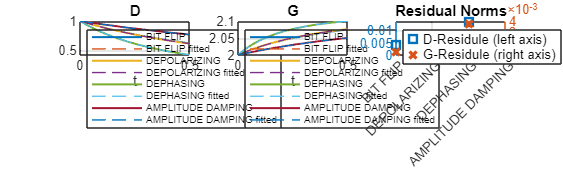

noise_type = 1


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3        0.00687631                              1.2
     1          6       0.000556716      0.00480811          0.00557      
     2          9       0.000556594     2.19065e-05         1.23e-07      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           98.0457                               99
     1          8           18.0456         3.27212             35.8      
     2         12            3.0978         4.31438             12.6      
     3         16          0.368708         1.48568             1.74      
     4         20          0.116291         5.94051             1.83      
     5         24         0.0272225        0.256203             0.16      
     6         28         0.0272225         2.06107             0.16      
     7         32         0.0181876        0.515267            0.113      
     8         36         0.0181876         1.03053            0.113      
     9         40         0.0134987        0.257634            0.107      
    10         44         0.0101914        0.515267            0.289      
    11         48        0.00422649      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4            206.45                              144
     1          8         0.0204427         1.72521             1.12      
     2         12       0.000830456        0.127307           0.0317      
     3         16       0.000808375       0.0105166         0.000823      
     4         20       0.000808375        0.221482         0.000823      
     5         24       0.000795795       0.0553705            0.014      
     6         28       0.000787486       0.0197292          0.00217      
     7         32       0.000787486        0.113499          0.00217      
     8         36         0.0007793       0.0276853          0.00377      
     9         40       0.000764576       0.0553705           0.0158      
    10         44       0.000753889       0.0220407          0.00288      
    11         48       0.000753889      

noise_type = 2


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3        0.00801725                             1.35
     1          6       6.09459e-05      0.00539202            0.007      
     2          9       6.07523e-05     2.75714e-05         1.94e-07      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           98.4958                             99.2
     1          8           18.1777         3.28869               36      
     2         12           3.15017         4.37487             12.8      
     3         16          0.376503         1.45712             1.76      
     4         20          0.140951          6.1477             2.05      
     5         24         0.0323864        0.114314            0.103      
     6         28         0.0323864         1.19556            0.103      
     7         32          0.020806        0.298891           0.0943      
     8         36         0.0131249        0.597782            0.181      
     9         40        0.00987302        0.602678             0.34      
    10         44        0.00339959       0.0398684           0.0112      
    11         48        0.00211367      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4            206.62                              144
     1          8         0.0195011         1.72056             1.09      
     2         12       0.000795131        0.124908           0.0305      
     3         16       0.000774436       0.0109142         0.000881      
     4         20       0.000774436        0.215104         0.000881      
     5         24       0.000761773       0.0537761           0.0135      
     6         28       0.000753182       0.0210667          0.00247      
     7         32       0.000753182        0.104129          0.00247      
     8         36       0.000745298       0.0260322          0.00338      
     9         40       0.000730843       0.0520643           0.0141      
    10         44       0.000719724       0.0249439          0.00365      
    11         48       0.000710432      

noise_type = 3


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3           0.03178                             2.68
     1          6       0.000238234       0.0106858           0.0275      
     2          9       0.000235219     0.000109091         3.02e-06      
     3         12       0.000235219     1.19648e-08          1.1e-10      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                              


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           127.475                              113
     1          8           27.5325         4.08027             45.8      
     2         12           7.65772         8.10213             21.7      
     3         16           1.06415         1.88514             3.93      
     4         20          0.634711              10             3.75      
     5         24          0.142999         1.20624            0.366      
     6         28          0.142999         1.29248            0.366      
     7         32         0.0904916        0.323119            0.287      
     8         36         0.0545221        0.646238            0.696      
     9         40         0.0163194        0.201099           0.0781      
    10         44        0.00868766        0.646238            0.179      
    11         48        0.00282955      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           213.002                              146
     1          8         0.0126171         1.67049            0.754      
     2         12        0.00417145       0.0849724           0.0142      
     3         16        0.00410547       0.0709706           0.0293      
     4         20        0.00405107       0.0410466           0.0105      
     5         24        0.00398184        0.111322           0.0734      
     6         28        0.00387686       0.0302777           0.0057      
     7         32        0.00380369       0.0556609           0.0184      
     8         36        0.00369799        0.110603           0.0723      
     9         40        0.00356215       0.0508945           0.0132      
    10         44        0.00342746        0.111322           0.0647      
    11         48        0.00324824      

noise_type = 4


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3        0.00201432                            0.675
     1          6       1.55267e-05        0.002709          0.00177      
     2          9       1.55144e-05     6.93329e-06         1.23e-08      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           81.4851                             90.1
     1          8           13.6492         2.71722             29.7      
     2         12            1.9185         2.21566             7.29      
     3         16          0.318705        0.600827            0.642      
     4         20         0.0246968        0.870918            0.363      
     5         24        0.00651881        0.300279           0.0402      
     6         28        0.00651881        0.633755           0.0402      
     7         32        0.00504441        0.158439           0.0468      
     8         36        0.00369051        0.316877           0.0799      
     9         40        0.00369051        0.675565           0.0799      
    10         44        0.00294044        0.158439            0.029      
    11         48        0.00233538      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           201.583                              142
     1          8          0.454923         1.73659             6.67      
     2         12       0.000127596        0.150485           0.0413      
     3         16       9.67418e-05      0.00591911         0.000128      
     4         20       9.67418e-05         0.19994         0.000128      
     5         24       9.54821e-05       0.0499849            0.008      
     6         28       9.44117e-05       0.0048386         0.000122      
     7         32       9.30734e-05       0.0499849          0.00862      
     8         36       9.18458e-05      0.00499906         0.000138      
     9         40       9.04317e-05       0.0499849          0.00928      
    10         44       8.90162e-05      0.00521941         0.000157      
    11         48        8.7522e-05      

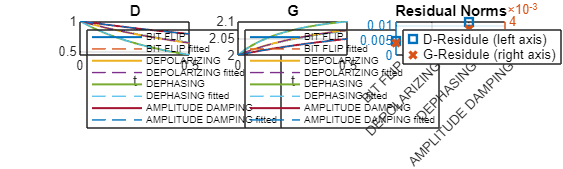

noise_type = 1


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3        0.00878373                             1.35
     1          6       0.000823172       0.0053936          0.00701      
     2          9       0.000822979     2.75893e-05         1.94e-07      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           102.416                              101
     1          8           19.3391         3.41199             37.4      
     2         12           3.61143         4.88425               14      
     3         16          0.433455         1.56661             2.03      
     4         20          0.314944         7.33457             3.12      
     5         24         0.0621194         1.21899            0.322      
     6         28         0.0621194         1.83364            0.322      
     7         32         0.0463922        0.458411            0.179      
     8         36         0.0463922        0.916822            0.179      
     9         40         0.0301998        0.229205            0.287      
    10         44          0.019626        0.458411             0.11      
    11         48          0.019626      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           207.545                              144
     1          8         0.0170816         1.70801             1.01      
     2         12        0.00100734        0.116781           0.0265      
     3         16       0.000988843       0.0144219          0.00146      
     4         20       0.000988843        0.180001          0.00146      
     5         24       0.000974242       0.0450001          0.00989      
     6         28        0.00096007       0.0358116          0.00693      
     7         32       0.000941075       0.0531106           0.0152      
     8         36       0.000926333       0.0286826          0.00484      
     9         40       0.000908538       0.0863473           0.0417      
    10         44       0.000878363       0.0173367           0.0019      
    11         48       0.000867638      

noise_type = 2


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3          0.009855                             1.49
     1          6       6.62209e-05      0.00597773          0.00861      
     2          9       6.59282e-05     3.39148e-05         2.93e-07      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4            102.94                              101
     1          8           19.4989         3.42955             37.6      
     2         12           3.68087         4.95357             14.2      
     3         16          0.444297         1.54091             2.06      
     4         20          0.369344          7.5336             3.37      
     5         24         0.0708163         1.41388            0.435      
     6         28         0.0708163          1.8834            0.435      
     7         32         0.0518605         0.47085            0.193      
     8         36         0.0518605        0.941699            0.193      
     9         40         0.0307776        0.235425            0.179      
    10         44          0.020792         0.47085            0.108      
    11         48          0.020792      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           207.736                              144
     1          8         0.0163538         1.70396            0.992      
     2         12        0.00100775        0.114523           0.0254      
     3         16       0.000989817       0.0153979          0.00163      
     4         20       0.000989817        0.170491          0.00163      
     5         24       0.000975284       0.0426228          0.00899      
     6         28       0.000959303       0.0407728          0.00898      
     7         32       0.000941541        0.043862           0.0106      
     8         36       0.000923264       0.0410684          0.00964      
     9         40       0.000901658       0.0490044           0.0139      
    10         44       0.000881075       0.0392572          0.00918      
    11         48       0.000853923      

noise_type = 3


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3         0.0390576                             2.97
     1          6       0.000259268       0.0118394           0.0338      
     2          9       0.000254714     0.000134135         4.55e-06      
     3         12       0.000254714     1.80995e-08         3.52e-12      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                              


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           135.985                              116
     1          8           30.6375         4.29993             48.5      
     2         12           9.45673         9.20685               24      
     3         16           1.44606         1.21112             4.55      
     4         20          0.710015              10             3.48      
     5         24          0.174336         0.57659            0.359      
     6         28          0.174336         1.25208            0.359      
     7         32            0.1105         0.31302             0.33      
     8         36           0.06561         0.62604            0.625      
     9         40         0.0223425         0.17507           0.0742      
    10         44          0.011276         0.62604            0.143      
    11         48        0.00443755      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           214.436                              146
     1          8         0.0121213         1.66005            0.686      
     2         12        0.00524487       0.0767381           0.0119      
     3         16        0.00515905        0.104062           0.0632      
     4         20        0.00506782        0.030159          0.00616      
     5         24        0.00506782        0.221716          0.00616      
     6         28        0.00498994       0.0554291           0.0183      
     7         32        0.00487162        0.103712            0.066      
     8         36        0.00474299       0.0469368            0.013      
     9         40         0.0045986        0.110858           0.0708      
    10         44        0.00441518        0.070137            0.024      
    11         48        0.00423004      

noise_type = 4


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3        0.00247648                            0.748
     1          6       1.68195e-05      0.00300436          0.00217      
     2          9        1.6801e-05     8.53115e-06         1.85e-08      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           83.6904                             91.4
     1          8           14.1846         2.79942             30.5      
     2         12           2.00798          2.4959             7.99      
     3         16          0.313405        0.294399            0.675      
     4         20         0.0150141         1.17333            0.192      
     5         24         0.0150141        0.759321            0.192      
     6         28         0.0093449         0.18983             0.03      
     7         32        0.00536248        0.379661            0.219      
     8         36        0.00323997          0.2735           0.0917      
     9         40         0.0024226        0.305413            0.139      
    10         44         0.0014439       0.0525187          0.00977      
    11         48        0.00122551      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           202.308                              142
     1          8         0.0801681         1.77301              2.6      
     2         12       0.000174361        0.159821           0.0519      
     3         16       0.000125554      0.00747821          0.00019      
     4         20       0.000125554        0.189948          0.00019      
     5         24       0.000123653       0.0474869          0.00783      
     6         28       0.000122427      0.00670654         0.000224      
     7         32       0.000120384       0.0474869          0.00841      
     8         36       0.000118992       0.0069234         0.000252      
     9         40       0.000116803       0.0474869          0.00901      
    10         44       0.000115213      0.00722131         0.000287      
    11         48       0.000112866      

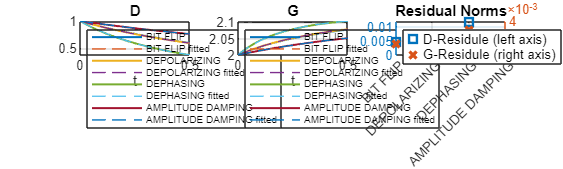

noise_type = 1


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3        0.00562467                             1.07
     1          6        0.00056857      0.00430246          0.00446      
     2          9       0.000568492     1.75272e-05         7.77e-08      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           90.6911                             95.2
     1          8           16.0207         3.02559             33.1      
     2         12           2.44255         3.31994             10.1      
     3         16          0.332919        0.817789             1.08      
     4         20         0.0396654         4.05539            0.684      
     5         24         0.0396654         1.83805            0.684      
     6         28         0.0234361        0.459513           0.0814      
     7         32         0.0234361          1.0583           0.0814      
     8         36         0.0180005        0.229756           0.0891      
     9         40            0.0135        0.459513            0.131      
    10         44            0.0135          1.0192            0.131      
    11         48         0.0109526      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           204.472                              143
     1          8         0.0284654         1.75975             1.33      
     2         12       0.000295603        0.149771           0.0448      
     3         16       0.000258634      0.00716528         0.000246      
     4         20       0.000258634        0.233037         0.000246      
     5         24        0.00025547       0.0582594           0.0135      
     6         28       0.000252315      0.00714943          0.00031      
     7         32       0.000248928       0.0582594           0.0146      
     8         36       0.000245262      0.00760751         0.000362      
     9         40       0.000241638       0.0582594           0.0157      
    10         44       0.000237387      0.00824432         0.000433      
    11         48       0.000233488      

noise_type = 2


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3        0.00491098                             1.05
     1          6       5.10675e-05      0.00421833          0.00429      
     2          9       5.09951e-05     1.68451e-05         7.21e-08      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           90.5748                             95.1
     1          8           15.9637         3.02986             33.1      
     2         12           2.42149         3.35471             10.2      
     3         16          0.315352        0.872941             1.11      
     4         20         0.0320008         4.04876            0.684      
     5         24         0.0320008         1.71698            0.684      
     6         28         0.0166966        0.429246           0.0703      
     7         32         0.0166966        0.945049           0.0703      
     8         36          0.012005        0.214623           0.0757      
     9         40        0.00929444        0.429246            0.341      
    10         44        0.00386699        0.168961           0.0513      
    11         48        0.00336601      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           204.434                              143
     1          8         0.0273189         1.75454              1.3      
     2         12       0.000448819         0.14604           0.0425      
     3         16       0.000414217      0.00772255         0.000358      
     4         20       0.000414217        0.248101         0.000358      
     5         24       0.000408221       0.0620252           0.0156      
     6         28       0.000403469      0.00960234         0.000547      
     7         32       0.000396875       0.0620252            0.017      
     8         36       0.000391254       0.0103403         0.000659      
     9         40       0.000383981       0.0620252           0.0183      
    10         44       0.000377345       0.0113966         0.000814      
    11         48       0.000369265      

noise_type = 3


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3         0.0195001                              2.1
     1          6       0.000200166      0.00837574           0.0169      
     2          9       0.000199033     6.68046e-05         1.13e-06      
     3         12       0.000199033     4.48181e-09         2.34e-10      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                              


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           113.247                              106
     1          8           22.6975         3.69915               41      
     2         12            5.0904         6.25224             17.4      
     3         16          0.613386         2.28982             2.92      
     4         20          0.613386         9.99619             2.92      
     5         24          0.297277         2.49905            0.299      
     6         28          0.163312         1.74713              1.7      
     7         32         0.0383438        0.763552            0.408      
     8         36          0.029736         1.17797            0.633      
     9         40         0.0057231        0.138621           0.0233      
    10         44         0.0031251        0.294494            0.151      
    11         48       0.000852402      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           210.187                              145
     1          8         0.0148565         1.69291            0.901      
     2         12        0.00247616        0.102317           0.0203      
     3         16        0.00244827       0.0314981          0.00604      
     4         20        0.00241308       0.0968486           0.0498      
     5         24        0.00236728       0.0192752          0.00254      
     6         28        0.00234875       0.0242122          0.00318      
     7         32        0.00231207       0.0484243           0.0134      
     8         36        0.00225866       0.0714683           0.0306      
     9         40        0.00221129       0.0408429           0.0102      
    10         44        0.00215092       0.0968486           0.0547      
    11         48        0.00207571      

noise_type = 4


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3        0.00123364                            0.527
     1          6       1.30885e-05      0.00211783          0.00108      
     2          9       1.30839e-05     4.23304e-06         4.58e-09      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           77.3578                             87.7
     1          8           12.6913         2.55996             28.1      
     2         12           1.80284         1.70035             6.05      
     3         16          0.310934         1.36754            0.535      
     4         20         0.0331587        0.556971            0.681      
     5         24        0.00397204         0.12919            0.107      
     6         28        0.00387106        0.424873            0.308      
     7         32        0.00164651       0.0373006          0.00798      
     8         36        0.00139126        0.106218           0.0109      
     9         40        0.00111493        0.212436           0.0746      
    10         44       0.000735731        0.142238           0.0385      
    11         48       0.000553497      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           200.152                              141
     1          8           1.96407         1.67153               14      
     2         12       5.81933e-05        0.166349           0.0239      
     3         16       4.78961e-05      0.00340459         5.05e-05      
     4         20       4.78961e-05        0.221294         5.05e-05      
     5         24       4.76598e-05       0.0553235          0.00811      
     6         28       4.67354e-05      0.00235991         3.55e-05      

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.



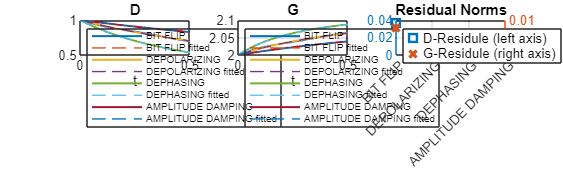


noise_types_list = [1,2,3,4];
lambda_list = 1:8;

for lambda=lambda_list
    D_resnorms = zeros(length(noise_types_list),1);
    G_resnorms = zeros(length(noise_types_list),1);
    fig_fit2 = figure(Position=[0,0,1280,384]);
    for i=1:length(noise_types_list)
        noise_type=noise_types_list(i)
        name = strcat(noise_type_str(noise_type+1), num2str(noise_p),...
            '_lambda',num2str(lambda),...
            '_offset',num2str(offset),...
            '_dt', num2str(dt),...
            '_nqubits',num2str(nqubits),...
            '_initCond',num2str(init_cond));
        load(strcat('DATA/MAT_',name,'.mat'));
        
        % Fitting data to single wave modelEq2
        D_opt = zeros(params.nsteps,1);
        G_opt = zeros(params.nsteps,1);
        u_resnorms = zeros(params.nsteps,1);% resnorm is the squared 2-norm of the residual(残差) at x: sum((fun(x,xdata)-ydata).^2).
        for j = 1:params.nsteps
            ui = u(j+1,:);
            % D G
            p_initial = [1.0, params.offset];
            lb =        [0,   -Inf         ];
            ub =        [Inf, Inf          ];
            options = optimoptions('lsqcurvefit', 'Display', 'iter', 'Algorithm','trust-region-reflective');
            [p_opt, u_resnorms(j)]=lsqcurvefit(@(p,x)u_model2(p,x,params.dt*(j)), p_initial, x, ui, lb, ub, options);
            D_opt(j) = p_opt(1);
            G_opt(j) = p_opt(2);
        end
    
        % Fitting data to modelEq_D
        %             [P    Q      R    ]
        p_initial_D = [1.0, -1,    1  ];
        lb =          [0,   -Inf,  0    ];
        ub =          [Inf, 0,     Inf  ];
        options = optimoptions('lsqcurvefit', 'Display', 'iter', 'Algorithm','trust-region-reflective');
        [p_opt_D, D_resnorm]=lsqcurvefit(@(p,t)D_model(p,t), p_initial_D, t(2:end)', D_opt, lb, ub, options);
        P=p_opt_D(1);
        Q=p_opt_D(2);
        R=p_opt_D(3);
        D_resnorms(i)=D_resnorm;
    
        % Fitting data to modelEq_G
        %             [X        Y                Z    ]
        p_initial_G = [1.0,     -1,              1  ];
        lb =          [-Inf,    -Inf,            0 ];
        ub =          [0,       0,               Inf  ];
        options = optimoptions('lsqcurvefit', 'Display', 'iter', 'Algorithm','trust-region-reflective');
        [p_opt_G, G_resnorm]=lsqcurvefit(@(p,t)G_model(p,t), p_initial_G, t(2:end)', G_opt, lb, ub, options);
        X=p_opt_G(1);
        Y=p_opt_G(2);
        Z=p_opt_G(3);
        G_resnorms(i)=G_resnorm;
    
        save(strcat('DATA/SingleFit2_',name,'.mat'),"D_opt","G_opt", ...
            "u_resnorms","params", ...
            "u","X","Y","Z","P","Q","R","D_resnorm","G_resnorm");
    
        % Plot
        subplot(1,3,1);
        hold on;
        plot(t(2:end), D_opt, 'DisplayName',noise_type_str(noise_type+1),'LineWidth',1.2);
        plot(t,D_model(p_opt_D,t),'--', 'DisplayName',strcat(noise_type_str(noise_type+1), " fitted") ,'LineWidth', 0.8);
        hold off;
    
        subplot(1,3,2);
        hold on;
        plot(t(2:end),G_opt(1:end),LineWidth=1.2,DisplayName=noise_type_str(noise_type+1));
        plot(t,G_model(p_opt_G,t),'--', 'DisplayName',strcat(noise_type_str(noise_type+1), " fitted"), 'LineWidth', 0.8);
        hold off;
    end
    % Adjust format
    subplot(1,3,1);
    box on; grid on;
    legend(Location="southwest", Color='none',FontSize=6); 
    xlabel('t');
    title('D');
        
    subplot(1,3,2);
    legend('location','northwest',Color='none', FontSize=6)
    xlabel('t');
    title('G')
    box on; grid on;
        
    subplot(1,3,3);
    hold on;
    yyaxis right;
    scatter(1:length(noise_types_list),sqrt(G_resnorms),Marker="x", LineWidth=2, DisplayName="G-Residule (right axis)");
    yyaxis left;
    scatter(1:length(noise_types_list),sqrt(D_resnorms),Marker="square",LineWidth=2, DisplayName="D-Residule (left axis)");
    hold off;
    
    title('Residual Norms')
    xticks(1:length(noise_types_list)); xticklabels(noise_type_str(noise_types_list+1));
    box on; grid on;
    legend(Location="northwest",FontSize=8);
    
    % Save figure
    figname=strcat('p', num2str(noise_p),...
        '_lambda',num2str(lambda),...
        '_offset',num2str(offset),...
        '_dt', num2str(dt),...
        '_nqubits',num2str(nqubits));
    savefig(fig_fit2, strcat('FIG/SingleFit2_', figname,'.fig'))
    exportgraphics(fig_fit2, strcat('FIG/SingleFit2_', figname,'.pdf'));
end